# Taller 1, punto 10: Adaline sobre las particiones de Iris

Igual que el punto 4 pero con adaline.m. Los mismos dos problemas: A) setosa contra el resto (separable) B) versicolor contra virginica (no separable) La salida deseada va en [0,1] y se clasifica con umbral 0.5.

clear; close all; clc
load iris_splits.mat
if ~exist('informe/figuras', 'dir'), mkdir('informe/figuras'); end
if ~exist('informe/tablas', 'dir'),  mkdir('informe/tablas');  end

## Parametros

op.umbral     = 0.5;
op.salida     = [0 1];
op.error_min  = 1e-3;
op.max_epocas = 500;
op.semilla    = 1;
alphas = [0.001 0.005 0.01 0.05 0.1];

problemas = {'A: setosa vs resto', 'B: versicolor vs virginica'};

## Entrenamiento

filas = {};
curvas = {};
for pr = 1:2
    for k = 1:numel(S)
        if pr == 1
            Xtr = S(k).Xtr;  Xte = S(k).Xte;
            dtr = double(S(k).ytr == 1);  dte = double(S(k).yte == 1);
        else
            mtr = S(k).ytr ~= 1;  mte = S(k).yte ~= 1;
            Xtr = S(k).Xtr(mtr, :);  Xte = S(k).Xte(mte, :);
            dtr = double(S(k).ytr(mtr) == 2);  dte = double(S(k).yte(mte) == 2);
        end
        mn = min(Xtr); mx = max(Xtr);
        Xtr = (Xtr - mn) ./ (mx - mn);
        Xte = (Xte - mn) ./ (mx - mn);

        for a = alphas
            o = op; o.alpha = a;
            [w, b, info] = adaline(Xtr, dtr, o);
            acc_tr = mean(predecir(Xtr, w, b, o.umbral, o.salida) == dtr);
            acc_te = mean(predecir(Xte, w, b, o.umbral, o.salida) == dte);
            etiqueta = sprintf('%d-%d', round(100*S(k).p), round(100*(1-S(k).p)));
            filas(end+1, :) = {problemas{pr}, etiqueta, a, info.epocas, info.ec_final, ...
                               info.convergio, 100*acc_tr, 100*acc_te}; %#ok<SAGROW>
            if k == 1 && a == 0.01, curvas{pr} = info.ec_por_epoca; end %#ok<SAGROW>
        end
    end
end
R = cell2table(filas, 'VariableNames', ...
    {'Problema', 'Particion', 'Alpha', 'Epocas', 'EC_final', 'Convergio', 'Exact_train', 'Exact_test'});
disp(R)

               Problema               Particion    Alpha    Epocas    EC_final    Convergio    Exact_train    Exact_test
    ______________________________    _________    _____    ______    ________    _________    ___________    __________

    {'A: setosa vs resto'        }    {'60-40'}    0.001     500      0.95925       false           100            100  
    {'A: setosa vs resto'        }    {'60-40'}    0.005     500      0.94532       false           100            100  
    {'A: setosa vs resto'        }    {'60-40'}     0.01     500      0.94854       false           100            100  
    {'A: setosa vs resto'        }    {'60-40'}     0.05     500      0.96619       false           100            100  
    {'A: setosa vs resto'        }    {'60-40'}      0.1     337       1.0079       true            100            100  
    {'A: setosa vs resto'        }    {'70-30'}    0.001     500       1.1164       false           100            100  
    {'A: setosa vs resto'      

writetable(R, 'informe/tablas/ada_iris.csv');

## Resumen por problema y particion

Res = groupsummary(R, {'Problema', 'Particion'}, 'mean', {'Epocas', 'EC_final', 'Exact_train', 'Exact_test'});
disp(Res)

               Problema               Particion    GroupCount    mean_Epocas    mean_EC_final    mean_Exact_train    mean_Exact_test
    ______________________________    _________    __________    ___________    _____________    ________________    _______________

    {'A: setosa vs resto'        }    {'60-40'}        5            467.4          0.96545               100                100     
    {'A: setosa vs resto'        }    {'70-30'}        5            450.8           1.1284               100                100     
    {'A: setosa vs resto'        }    {'80-20'}        5            446.2           1.3207               100                100     
    {'A: setosa vs resto'        }    {'90-10'}        5            430.8           1.4898               100                100     
    {'B: versicolor vs virginica'}    {'60-40'}        5            398.2           1.4607            98.214             93.636     
    {'B: versicolor vs virginica'}    {'70-30'}        5            

## Graficas

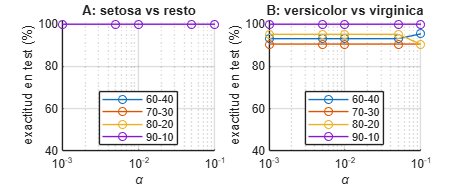

figure('Position', [100 100 950 380]);
for pr = 1:2
    subplot(1, 2, pr); hold on
    for k = 1:numel(S)
        etiqueta = sprintf('%d-%d', round(100*S(k).p), round(100*(1-S(k).p)));
        m = strcmp(R.Problema, problemas{pr}) & strcmp(R.Particion, etiqueta);
        plot(R.Alpha(m), R.Exact_test(m), '-o', 'DisplayName', etiqueta);
    end
    set(gca, 'XScale', 'log'); grid on; ylim([40 102]);
    xlabel('\alpha'); ylabel('exactitud en test (%)'); title(problemas{pr});
    legend('Location', 'best');
end
guardar_fig('ada_iris');

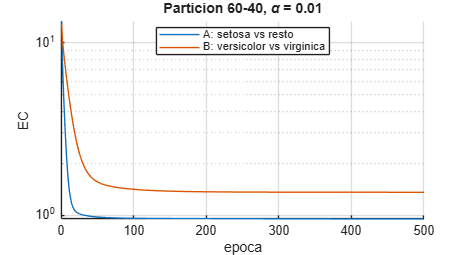


figure('Position', [100 100 700 380]); hold on
semilogy(curvas{1}, 'DisplayName', problemas{1});
semilogy(curvas{2}, 'DisplayName', problemas{2});
set(gca, 'YScale', 'log'); grid on
xlabel('epoca'); ylabel('EC'); title('Particion 60-40, \alpha = 0.01'); legend('Location', 'best');
guardar_fig('ada_iris_ec');